# Fase 5: Cribado de calidad 

## Pipeline de procesamiento de las imágenes para la extracción automática de características que permitan evaluar la calidad de las imágenes.

### 1. Carga de datos y análisis preliminar

clc; clear all; close all;

img_path = fullfile('..', '..', 'BaseDeDatos', 'RFI', 'raw'); % Definir la ruta relativa de las imagenes RFI raw.
revised_img_path = fullfile('..', '..', 'BaseDeDatos', 'RFI', 'Procesado', 'Revisadas'); % Definir la ruta relativa de las imagenes RFI revisadas.
test_img_path = fullfile('..', '..', 'BaseDeDatos', 'RFI', 'Procesado', 'Testeadas'); % Definir la ruta relativa de las imagenes RFI testeadas.

metadata_path = fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'PreProcessed.csv'); % Definir la ruta relativa de la tabla metadata.
models_path = fullfile('..', 'Modelos'); % Definir la ruta relativa de los modelos.

T = readtable(metadata_path); % Cargar la tabla de metadata.

Definir las características de la base de datos:

% Definir la codificación de imagenes de pacientes sanos y con glaucoma.
glaucoma = {0, 'Sano';1, 'Glaucoma'}; 

% Definir la codificación de imagenes no revidadas, de bajo contraste, con desenfoque, con ruido y de calidad correcta.
quality = { 
    0,'(0) Imagen no revisada';
    1,'(1) Bajo contraste';
    2,'(2) Desenfoque';
    3,'(3) Ruido';
    4,'(4) Calidad correcta'
};

% Calcular el número de imagenes de pacientes sanos y con glaucoma.
for i = 1:length(glaucoma)
    glaucoma{i,3} = sum(T.glaucoma == i-1);
    fprintf('Número de imágenes de tipo %s: %d \n', glaucoma{i,2}, glaucoma{i,3});
end

Número de imágenes de tipo Sano: 1130 
Número de imágenes de tipo Glaucoma: 440 


% Convertir el cell de glaucoma en tabla.
glaucoma = cell2table(glaucoma);
glaucoma = renamevars(glaucoma, 'glaucoma1', 'encoding');
glaucoma = renamevars(glaucoma, 'glaucoma2', 'class');
glaucoma = renamevars(glaucoma, 'glaucoma3', 'count');  

% Calcular el número de imagenes no revidadas, de bajo contraste, con desenfoque, con ruido y de calidad correcta.
for i = 1:length(quality)
    quality{i,3} = sum(T.quality == i-1);
    fprintf('Número de imágenes de tipo %s: %d \n', quality{i,2}, quality{i,3});
end

Número de imágenes de tipo (0) Imagen no revisada: 1261 
Número de imágenes de tipo (1) Bajo contraste: 51 
Número de imágenes de tipo (2) Desenfoque: 55 
Número de imágenes de tipo (3) Ruido: 54 
Número de imágenes de tipo (4) Calidad correcta: 149 


% Convertir el cell de quality en tabla.
quality = cell2table(quality);
quality = renamevars(quality, 'quality1', 'encoding');
quality = renamevars(quality, 'quality2', 'class');
quality = renamevars(quality, 'quality3', 'count');

### 2.Extracción automática de *features *de calidad de la imagen:

for i = 1:height(T)
    I = imread(string(fullfile(img_path, T{i,1})));

    % Parametros para cuantificar el bajo contraste:
    [T.entropy(i), ~, ~, ~, ~, ~] = CalcularMetricasCalidad(I); % Calcular la entropia de la imagen.
    [~, T.dynamic_range(i), ~, ~, ~, ~] = CalcularMetricasCalidad(I); % Calcular el rango dinámico de la imagen.
    [~, ~, T.contrast(i), ~, ~, ~] = CalcularMetricasCalidad(I); % Calcular el contraste de la imagen

    % Metricas para cuantificar el desenfoque y el ruido:
    [~, ~, ~, T.lap_max(i), ~, ~] = CalcularMetricasCalidad(I);
    [~, ~, ~, ~, T.lap_mean(i), ~] = CalcularMetricasCalidad(I);
    [~, ~, ~, ~, ~, T.lap_std(i)] = CalcularMetricasCalidad(I);

end  

features = T.Properties.VariableNames(4:end);
writetable(T, fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'PreProcessed.csv')); % Guardar la tabla con las features de las imágenes.

### 3.Análisis de correlación de features:

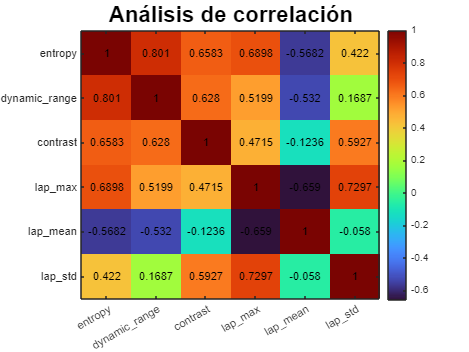

R = corr(double(T{:, T.Properties.VariableNames(4:end)})); % Obtener La matriz con los valores de correlaciones entre variables.

figure;
imagesc(R); title('Análisis de correlación', FontSize = 20); % Visualizar las correlaciones entre variables

xticks(1:length(T.Properties.VariableNames(4:end)));
xticklabels(T.Properties.VariableNames(4:end));

yticks(1:length(T.Properties.VariableNames(4:end)));
yticklabels(T.Properties.VariableNames(4:end));

colormap(turbo); colorbar;
for i = 1:size(R, 1)
    for j = 1:size(R, 2)
        text(j, i, num2str(round(R(i, j), 4)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'k');
    end
end

set(gca, 'TickLabelInterpreter', 'none');

### 4. Análisis de clases de imágenes revisadas:

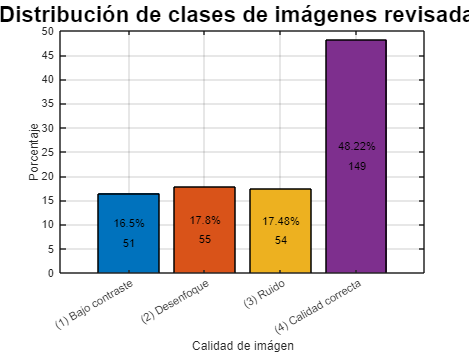

% Convertir la columna 'quality' a categórica
T_revised = T(T.quality ~= 0,:); % Crear una tabla con solo imágenes revisadas.
T_revised.quality = categorical(T_revised.quality);

% Contar la frecuencia de cada clase
class_counts = countcats(T_revised.quality);
total_samples = sum(class_counts);

% Calcular los porcentajes de frecuencia
class_percentages = (class_counts / total_samples) * 100;
class_percentages = round(class_percentages, 2);

% Etiquetas de las clases
class_labels = categorical(quality{2:5,2});

% Gráfico de barras para visualizar el desequilibrio de clases
b1 = bar(class_labels, class_percentages);
title('Distribución de clases de imágenes revisadas', FontSize = 20)
xlabel('Calidad de imágen')
ylabel('Porcentaje')
grid on
colors = lines(4);
b1.FaceColor = 'flat';
for i=1:4
    b1.CData(i,:) = colors(i,:);
end
hold on

% Mostrar el recuento de cada clase dentro de las barras
for i = 1:4
    text(b1.XData(i), b1.YData(i) / 2 - 2, num2str(class_counts(i)), ...
        'HorizontalAlignment', 'center');
    text(b1.XData(i), b1.YData(i) / 2 + 2, [num2str(class_percentages(i)), '%'], ...
        'HorizontalAlignment', 'center');
end

### 5. Entrenamiento de diferentes modelos con las imágenes revisadas:

rng(30); % Semilla para reproducibilidad.

results = table; % Crear tabla para guardar los parámetros de cada modelo.

inputTable = T_revised(:,3:end); % Tabla de imágenes revisadas para el entrenamiento.
predictorNames = {'entropy', 'dynamic_range', 'contrast', 'lap_max', 'lap_mean', 'lap_std'}; % Nombres de las features usadas para el entrenamiento
isCategoricalPredictor = [false, false, false, false, false, false];
classNames = categorical({'1'; '2'; '3'; '4'}); 
predictors = inputTable(:, predictorNames);
response = inputTable.quality;

quality_labels = quality.class(2:end)';
responseLabels = categorical(cellstr(quality_labels(response)));

#### 5.1. Classification Tree:

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 100, ...
    'Surrogate', 'off', ...
    'ClassNames', classNames);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
trainedClassifierTree.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifierTree.RequiredVariables = {'entropy', 'dynamic_range', 'contrast', 'lap_max', 'lap_mean', 'lap_std'};
trainedClassifierTree.ClassificationTree = classificationTree;
trainedClassifierTree.About = 'This struct is a trained model exported from Classification Learner R2024a.';
trainedClassifierTree.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  [yfit,scores] = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModel = crossval(trainedClassifierTree.ClassificationTree, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

Estimate test performance

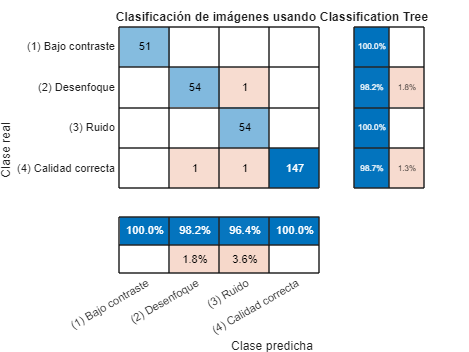

results = [results; table("Classification Tree", 1 - validationAccuracy, validationAccuracy, 'VariableNames',{'Modelo','Perdida','Precisión'})];

figure
cm = confusionchart(responseLabels,categorical(cellstr(quality_labels(validationPredictions))));
cm.Title = 'Clasificación de imágenes usando Classification Tree';

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Clase predicha';
cm.YLabel = 'Clase real';

Guardar modelo:

%save(fullfile(models_path,'trainedClassifierTree.mat'), 'trainedClassifierTree');

#### 5.2. K-Nearest Neighbors (KNN)

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationKNN = fitcknn(...
    predictors, ...
    response, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 3, ...
    'DistanceWeight', 'Equal', ...
    'Standardize', true, ...
    'ClassNames', classNames);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
knnPredictFcn = @(x) predict(classificationKNN, x);
trainedClassifierKNN.predictFcn = @(x) knnPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifierKNN.RequiredVariables = {'entropy', 'dynamic_range', 'contrast', 'lap_max', 'lap_mean', 'lap_std'};
trainedClassifierKNN.ClassificationKNN = classificationKNN;
trainedClassifierKNN.About = 'This struct is a trained model exported from Classification Learner R2024a.';
trainedClassifierKNN.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  [yfit,scores] = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModel = crossval(trainedClassifierKNN.ClassificationKNN, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

Estimate test performance

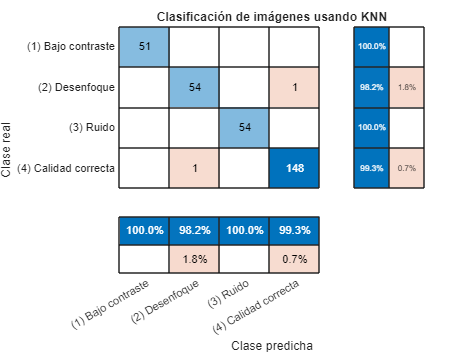

results = [results; table("K-Nearest Neighbors (KNN)", 1 - validationAccuracy, validationAccuracy, 'VariableNames',{'Modelo','Perdida','Precisión'})];

figure
cm = confusionchart(responseLabels,categorical(cellstr(quality_labels(validationPredictions))));
cm.Title = 'Clasificación de imágenes usando KNN';

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Clase predicha';
cm.YLabel = 'Clase real';

Guardar modelo:

%save(fullfile(models_path,'trainedClassifierKNN.mat'), 'trainedClassifierKNN');

#### 5.3. Naive Bayes

% Train a classifier
% This code specifies all the classifier options and trains the classifier.

% Expand the Distribution Names per predictor
% Numerical predictors are assigned either Gaussian or Kernel distribution and categorical predictors are assigned mvmn distribution
% Gaussian is replaced with Normal when passing to the fitcnb function
distributionNames =  repmat({'Kernel'}, 1, length(isCategoricalPredictor));
distributionNames(isCategoricalPredictor) = {'mvmn'};

if any(strcmp(distributionNames,'Kernel'))
    classificationNaiveBayes = fitcnb(...
        predictors, ...
        response, ...
        'Kernel', 'Normal', ...
        'Support', 'Unbounded', ...
        'Standardize', true, ...
        'DistributionNames', distributionNames, ...
        'ClassNames', classNames);
else
    classificationNaiveBayes = fitcnb(...
        predictors, ...
        response, ...
        'DistributionNames', distributionNames, ...
        'ClassNames', classNames);
end

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
naiveBayesPredictFcn = @(x) predict(classificationNaiveBayes, x);
trainedClassifierNB.predictFcn = @(x) naiveBayesPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifierNB.RequiredVariables = {'entropy', 'dynamic_range', 'contrast', 'lap_max', 'lap_mean', 'lap_std'};
trainedClassifierNB.ClassificationNaiveBayes = classificationNaiveBayes;
trainedClassifierNB.About = 'This struct is a trained model exported from Classification Learner R2024a.';
trainedClassifierNB.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  [yfit,scores] = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModel = crossval(trainedClassifierNB.ClassificationNaiveBayes, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

Estimate test performance

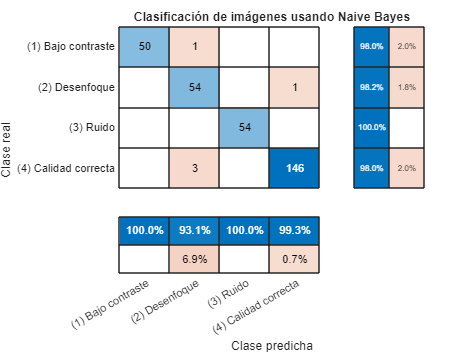

results = [results; table("Naive Bayes", 1 - validationAccuracy, validationAccuracy, 'VariableNames',{'Modelo','Perdida','Precisión'})];

figure
cm = confusionchart(responseLabels,categorical(cellstr(quality_labels(validationPredictions))));
cm.Title = 'Clasificación de imágenes usando Naive Bayes';

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Clase predicha';
cm.YLabel = 'Clase real';

Guardar modelo:

%save(fullfile(models_path,'trainedClassifierNB.mat'), 'trainedClassifierNB');

#### **5.4. Linear Discriminant Analysis**

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationDiscriminant = fitcdiscr(...
    predictors, ...
    response, ...
    'DiscrimType', 'linear', ...
    'Gamma', 0, ...
    'FillCoeffs', 'off', ...
    'ClassNames', classNames);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
discriminantPredictFcn = @(x) predict(classificationDiscriminant, x);
trainedClassifierLDA.predictFcn = @(x) discriminantPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifierLDA.RequiredVariables = {'entropy', 'dynamic_range', 'contrast', 'lap_max', 'lap_mean', 'lap_std'};
trainedClassifierLDA.ClassificationDiscriminant = classificationDiscriminant;
trainedClassifierLDA.About = 'This struct is a trained model exported from Classification Learner R2024a.';
trainedClassifierLDA.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  [yfit,scores] = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModel = crossval(trainedClassifierLDA.ClassificationDiscriminant, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

Estimate test performance

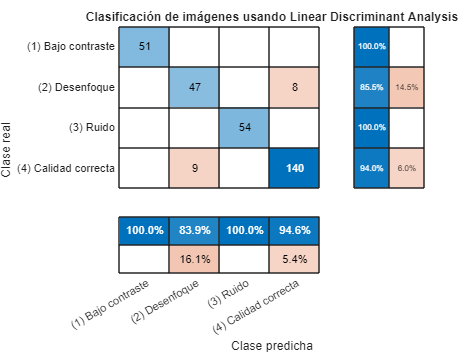

results = [results; table("Linear Discriminant Analysis", 1 - validationAccuracy, validationAccuracy, 'VariableNames',{'Modelo','Perdida','Precisión'})];

figure
cm = confusionchart(responseLabels,categorical(cellstr(quality_labels(validationPredictions))));
cm.Title = 'Clasificación de imágenes usando Linear Discriminant Analysis';

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Clase predicha';
cm.YLabel = 'Clase real';

Guardar modelo:

%save(fullfile(models_path,'trainedClassifierLDA.mat'), 'trainedClassifierLDA');

#### **5.5. Quadratic Support Vector Machines (SVM)**

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateSVM(...
    'KernelFunction', 'polynomial', ...
    'PolynomialOrder', 2, ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 1, ...
    'Standardize', true);
classificationSVM = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', classNames);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifierSVM.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifierSVM.RequiredVariables = {'entropy', 'dynamic_range', 'contrast', 'lap_max', 'lap_mean', 'lap_std'};
trainedClassifierSVM.ClassificationSVM = classificationSVM;
trainedClassifierSVM.About = 'This struct is a trained model exported from Classification Learner R2024a.';
trainedClassifierSVM.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  [yfit,scores] = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModel = crossval(trainedClassifierSVM.ClassificationSVM, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

Estimate test performance

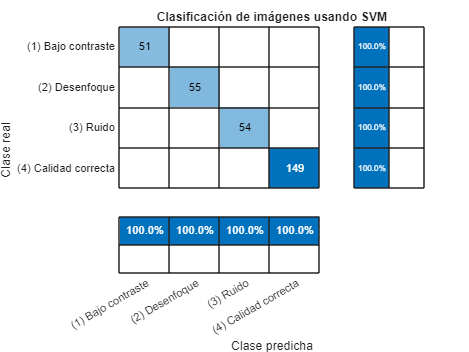

results = [results; table("Support Vector Machine (SVM)", 1 - validationAccuracy, validationAccuracy, 'VariableNames',{'Modelo','Perdida','Precisión'})];

figure
cm = confusionchart(responseLabels,categorical(cellstr(quality_labels(validationPredictions))));
cm.Title = 'Clasificación de imágenes usando SVM';

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Clase predicha';
cm.YLabel = 'Clase real';

Guardar modelo:

%save(fullfile(models_path,'trainedClassifierSVM.mat'), 'trainedClassifierSVM');

## Comparación de modelos

results

results = 5×3 table
                Modelo                 Perdida     Precisión
    ______________________________    _________    _________

    "Classification Tree"             0.0097087     0.99029 
    "K-Nearest Neighbors (KNN)"       0.0064725     0.99353 
    "Naive Bayes"                      0.016181     0.98382 
    "Linear Discriminant Analysis"     0.055016     0.94498 
    "Support Vector Machine (SVM)"            0           1 


[~, best_model] = min(results.Perdida);
results(best_model, :)

ans = 1×3 table
                Modelo                Perdida    Precisión
    ______________________________    _______    _________

    "Support Vector Machine (SVM)"       0           1    


## 6. Predicción y clasificación de imágenes no revisadas:

load(fullfile('..', 'Modelos', 'trainedClassifierSVM.mat')); % Cargar el mejor modelo entrenado seleccionado.

T_unrevised = T(T.quality == 0,:); % Tabla de las imágenes no revisadas.
T_tested = T_unrevised;

for i = 1:height(T_tested)
    [yfit ~] = trainedClassifierSVM.predictFcn(T_tested(i,4:end)); % Predecir la calidad de la imagen.
    T_tested.quality(i) = double(yfit);
end  

% Calcular el número de imagenes de bajo contraste, con desenfoque, con ruido y de calidad correcta de las no revidadas.
quality_tested = quality(2:end,:);
for i = 1:height(quality_tested)
    quality_tested{i,3} = sum(T_tested.quality == i);
    fprintf('Número de imágenes no revisadas de tipo %s: %d \n', char(quality_tested{i,2}), quality_tested{i,3});
end

Número de imágenes no revisadas de tipo (1) Bajo contraste: 11 
Número de imágenes no revisadas de tipo (2) Desenfoque: 7 
Número de imágenes no revisadas de tipo (3) Ruido: 8 
Número de imágenes no revisadas de tipo (4) Calidad correcta: 1235 


T_tested.quality = categorical(T_tested.quality);
T_preProcessed = vertcat(T_revised, T_tested);
T_preProcessed = sortrows(T_preProcessed, 'image');

T_correct = T_preProcessed(T_preProcessed.quality == categorical(4),:); % Tabla de las imágenes correctas

Guardar nuevas tablas de metadata:

writetable(T_revised, fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'Revised.csv')); % Guardar la tabla de imágenes revisadas.
writetable(T_unrevised, fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'Unrevised.csv')); % Guardar la tabla de imágenes no revisadas.
writetable(T_tested, fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'Tested.csv')); % Guardar la tabla de imágenes testeadas.

writetable(T_preProcessed, fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'PreProcessed2.csv')); % Guardar la tabla de imágenes preprocesadas

T_revised.quality = double(T_revised.quality);
T_revisedCorrect = T_revised(T_revised.quality == 4,:);

writetable(T_correct, fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'Correct.csv')); % Guardar la tabla de imágenes correctas.
writetable(T_revisedCorrect, fullfile('..', '..', 'BaseDeDatos', 'Metadata', 'RevisedCorrect.csv')); % Guardar la tabla de imágenes correctas.

## 7. Guardado de imágenes:

Guardar imágenes testeadas:

for i = 1:height(T_tested)
    I = imread(fullfile(img_path, T_tested.image{i}));
    if T_tested.quality(i) == 1
        imwrite(I, fullfile(test_img_path, 'Bajo Contraste', T_tested.image{i}));
    elseif T_tested.quality(i) == 2
        imwrite(I, fullfile(test_img_path, 'Testeadas', 'Desenfoque', T_tested.image{i}));
    elseif T_tested.quality(i) == 3
        imwrite(I, fullfile(test_img_path, 'Ruido', T_tested.image{i}));
    else 
        imwrite(I, fullfile(test_img_path, 'Calidad Correcta', T_tested.image{i}));
    end
end

Guardar imágenes revisadas

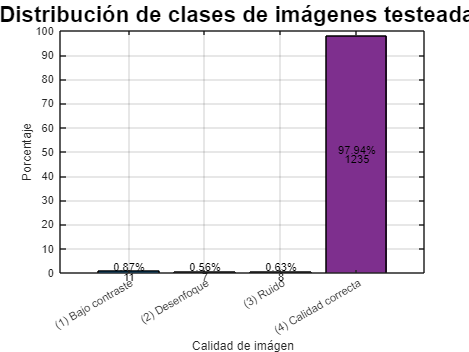

T_revised.quality = double(T_revised.quality);
for i = 1:height(T_revised)
    I = imread(fullfile(img_path, T_revised.image{i}));
    if T_revised.quality(i) == 1
        imwrite(I, fullfile(revised_img_path, 'Bajo Contraste', T_revised.image{i}));
    elseif T_revised.quality(i) == 2
        imwrite(I, fullfile(revised_img_path, 'Desenfoque', T_revised.image{i}));
    elseif T_revised.quality(i) == 3
        imwrite(I, fullfile(revised_img_path, 'Ruido', T_revised.image{i}));
    else 
        imwrite(I, fullfile(revised_img_path, 'Calidad Correcta', T_revised.image{i}));
    end
end

## 8. Análisis de cada tipo de imágenes:

Dajo Contraste

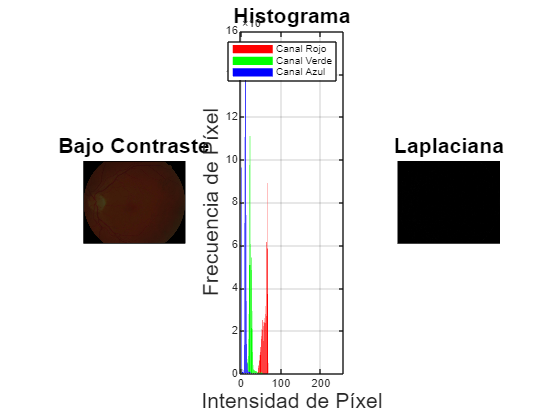

figure

I1 = imread(fullfile(revised_img_path, "Bajo Contraste", "image_0315.jpg"));
l1 = imfilter(double(rgb2gray(I1)), fspecial('laplacian')); 
subplot(1,3,1); imshow(I1); title('Bajo Contraste', 'Fontsize', 16);

IR1 = I1(:,:,1); [HR1, IR1] = imhist(IR1);
IG1 = I1(:,:,2); [HG1, IG1] = imhist(IG1);
IB1 = I1(:,:,3); [HB1, IB1] = imhist(IB1);

subplot(1,3,2);
bar(IR1, HR1, 'FaceColor', [1 0 0]);
grid on
hold on
bar(IG1, HG1, 'FaceColor', [0 1 0]);
bar(IB1, HB1, 'FaceColor', [0 0 1]);
title('Histograma', 'Fontsize', 16)
xlabel('Intensidad de Píxel', 'Fontsize', 16);
ylabel('Frecuencia de Píxel', 'Fontsize', 16);
legend('Canal Rojo', 'Canal Verde', 'Canal Azul')

subplot(1,3,3);
imshow(uint8(l1));
title('Laplaciana', 'Fontsize', 16)

Desenfoque

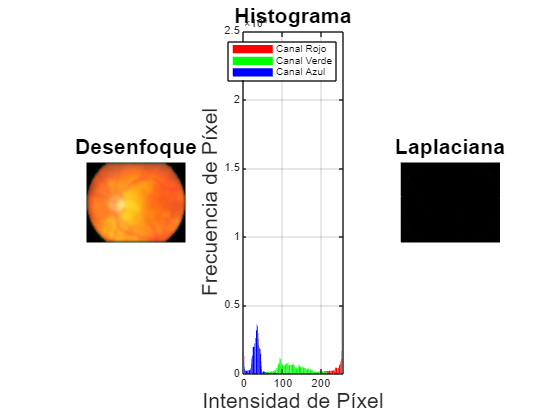

figure

I2 = imread(fullfile(revised_img_path, "Desenfoque", "image_0639.jpg"));
l2 = imfilter(double(rgb2gray(I2)), fspecial('laplacian')); 
subplot(1,3,1); imshow(I2); title('Desenfoque', 'Fontsize', 16);

IR2 = I2(:,:,1); [HR2, IR2] = imhist(IR2);
IG2 = I2(:,:,2); [HG2, IG2] = imhist(IG2);
IB2 = I2(:,:,3); [HB2, IB2] = imhist(IB2);

subplot(1,3,2);
bar(IR2, HR2, 'FaceColor', [1 0 0]);
grid on
hold on
bar(IG2, HG2, 'FaceColor', [0 1 0]);
bar(IB2, HB2, 'FaceColor', [0 0 1]);
title('Histograma', 'Fontsize', 16)
xlabel('Intensidad de Píxel', 'Fontsize', 16);
ylabel('Frecuencia de Píxel', 'Fontsize', 16);
legend('Canal Rojo', 'Canal Verde', 'Canal Azul')

subplot(1,3,3);
imshow(uint8(l2));
title('Laplaciana', 'Fontsize', 16)

Ruido

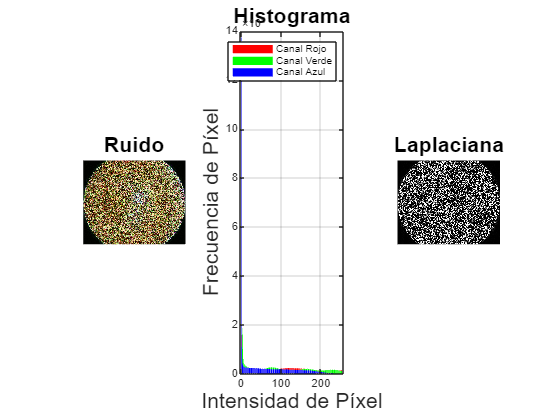

figure

I3 = imread(fullfile(revised_img_path, "Ruido", "image_0068.jpg"));
l3 = imfilter(double(rgb2gray(I3)), fspecial('laplacian')); 
subplot(1,3,1); imshow(I3); title('Ruido', 'Fontsize', 16);

IR3 = I3(:,:,1); [HR3, IR3] = imhist(IR3);
IG3 = I3(:,:,2); [HG3, IG3] = imhist(IG3);
IB3 = I3(:,:,3); [HB3, IB3] = imhist(IB3);

subplot(1,3,2);
bar(IR3, HR3, 'FaceColor', [1 0 0]);
grid on
hold on
bar(IG3, HG3, 'FaceColor', [0 1 0]);
bar(IB3, HB3, 'FaceColor', [0 0 1]);
title('Histograma', 'Fontsize', 16)
xlabel('Intensidad de Píxel', 'Fontsize', 16);
ylabel('Frecuencia de Píxel', 'Fontsize', 16);
legend('Canal Rojo', 'Canal Verde', 'Canal Azul')

subplot(1,3,3);
imshow(uint8(l3));
title('Laplaciana', 'Fontsize', 16)

Calidad Correcta

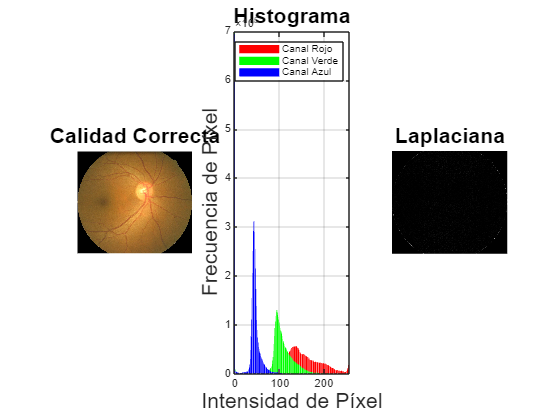

figure

I4 = imread(fullfile(revised_img_path, "Calidad Correcta", "image_0314.jpg"));
l4 = imfilter(double(rgb2gray(I4)), fspecial('laplacian')); 
subplot(1,3,1); imshow(I4); title('Calidad Correcta', 'Fontsize', 16)

IR4 = I4(:,:,1); [HR4, IR4] = imhist(IR4);
IG4 = I4(:,:,2); [HG4, IG4] = imhist(IG4);
IB4 = I4(:,:,3); [HB4, IB4] = imhist(IB4);

subplot(1,3,2);
bar(IR4, HR4, 'FaceColor', [1 0 0]);
grid on
hold on
bar(IG4, HG4, 'FaceColor', [0 1 0]);
bar(IB4, HB4, 'FaceColor', [0 0 1]);
title('Histograma', 'Fontsize', 16)
xlabel('Intensidad de Píxel', 'Fontsize', 16);
ylabel('Frecuencia de Píxel', 'Fontsize', 16);
legend('Canal Rojo', 'Canal Verde', 'Canal Azul')
subplot(1,3,3);
imshow(uint8(l4));
title('Laplaciana', 'Fontsize', 16)

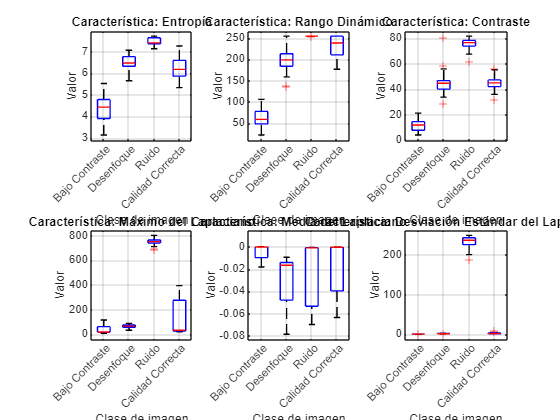

T1 = T(find(T.quality == 1),4:end);
T2 = T(find(T.quality == 2),4:end);
T3 = T(find(T.quality == 3),4:end);
T4 = T(find(T.quality == 4),4:end);

medias1 = mean(T1);
medias2 = mean(T2);
medias3 = mean(T3);
medias4 = mean(T4);

% Supongamos que tus tablas están almacenadas en las variables T1, T2, T3 y T4
% Primero, necesitamos concatenar todas las tablas en una sola
Ta = [T1; T2; T3; T4];

% Luego, creamos un vector de etiquetas para cada clase de imagen
clases = [repmat({'Bajo Contraste'}, height(T1), 1); repmat({'Desenfoque'}, height(T2), 1); repmat({'Ruido'}, height(T3), 1); repmat({'Calidad Correcta'}, height(T4), 1)];

% Las características son: Entropía, Rango Dinámico, Contraste, Máximo del Laplaciano, Media del Laplaciano y Desviación Estándar del Laplaciano
carac = {'Entropía', 'Rango Dinámico', 'Contraste', 'Máximo del Laplaciano', 'Media del Laplaciano', 'Desviación Estándar del Laplaciano'};

figure; k = 1;
% Ahora, para cada característica (columna en T), creamos un boxplot
for i = 1:width(Ta)
    subplot(2,3,k)
    k = k + 1;
    boxplot(Ta{:,i}, clases);
    grid on
    title(['Característica: ' carac{i}]);
    xlabel('Clase de imagen');
    ylabel('Valor');
end

for i = 1:height(T)
    I = imread(fullfile(img_path, T.image{i}));
    if T.glaucoma(i) == 1
        imwrite(I, fullfile(test_img_path, 'Glaucoma', T.image{i}));
    else 
        imwrite(I, fullfile(test_img_path, 'Sano', T.image{i}));
    end
end